clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = 7211.54e3;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Constantes de la memoria
eta     = n*t/2;
alpha1  =     omega +   theta_0;
alpha2  =   2*omega +   theta_0;
alpha3  =   2*omega + 3*theta_0;
alpha4  =     omega + 2*theta_0;
alpha5  =     omega + 3*theta_0;
alpha6  =     omega -   theta_0;


beta1   =       eta +    alpha1;
beta2   =     3*eta +  2*alpha1;
beta3   =       eta +  2*alpha1;
beta4   =       eta -  2*alpha1;
beta5   =     2*eta +    alpha1;
beta6   =     3*eta +    alpha1;
beta7   =     4*eta +    alpha1;
beta8   =    -  eta +    alpha1;
beta9   =   - 2*eta +    alpha1;

beta10  =     2*eta +    alpha2;
beta11  =     4*eta +    alpha2;
beta12  =   - 2*eta +    alpha2;

beta13  =    4*eta +    alpha3;
beta14  =    6*eta +    alpha3;
beta15  =  - 2*eta +    alpha3;

beta16  =      eta +    alpha4;
beta17  =    2*eta +    alpha4;
beta18  =    3*eta +    alpha4;
beta19  =    4*eta +    alpha4;
beta20  =    - eta +    alpha4;
beta21  =  - 2*eta +    alpha4;

beta22  =     2*eta +    alpha5;
beta23  =     4*eta +    alpha5;
beta24  =     6*eta +    alpha5;
beta25  =   - 2*eta +    alpha5;

beta26  =     2*eta +    alpha6;
beta27  =   - 2*eta +    alpha6;


tau1    =     2*eta +   theta_0;
tau2    =   - 2*eta +   theta_0;
o1      =       eta +     omega;
o2      =     2*eta +     omega;
o3      =     - eta +     omega;
o4      =   - 2*eta +     omega;
zeta_i  = sin(INC) + 5*sin(3*INC);
zeta_a1 = sin(alpha1) + 5*sin(3*alpha1);

u = beta5;

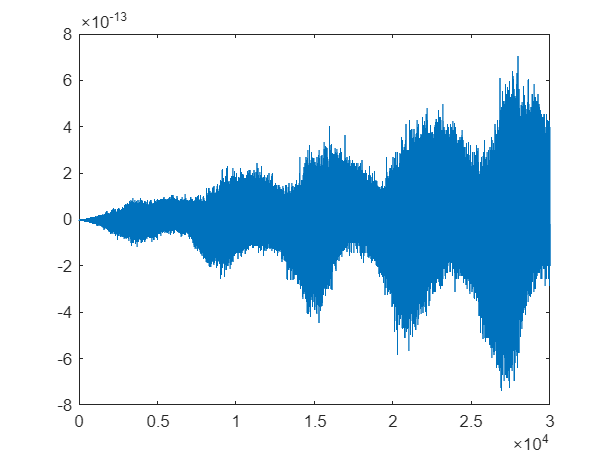

% Solución analítica
xJ3B =  (((15.*R.^3.*n.*sin(n.*t).*sin(INC).^3.*cos(omega))./8 - 6.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).*sin(omega) - (15.*R.^3.*n.^2.*t.*sin(INC).^3.*cos(omega))./8 - (5.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*cos(omega))./8 - (15.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3.*sin(omega))./8 + 15.*R.^3.*n.*sin((n.*t)./2).^4.*sin(INC).^3.*sin(omega) - 15.*R.^3.*n.*sin((n.*t)./2).^6.*sin(INC).^3.*sin(omega) - (3.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega))./2 + (3.*R.^3.*n.^2.*t.*sin(INC).*cos(omega))./2 + (5.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3.*sin(omega).^3)./2 + 10.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^3 - 20.*R.^3.*n.*sin((n.*t)./2).^4.*sin(INC).^3.*sin(omega).^3 + 20.*R.^3.*n.*sin((n.*t)./2).^6.*sin(INC).^3.*sin(omega).^3 + (15.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).^3.*sin(omega))./8 + (15.*R.^3.*n.^2.*t.*sin((n.*t)./2).^2.*sin(INC).^3.*cos(omega))./4 - (3.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega))./2 + (5.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*cos(omega).*sin(omega).^2)./2 - 3.*R.^3.*n.^2.*t.*sin((n.*t)./2).^2.*sin(INC).*cos(omega))./(a.^2.*n)).*J3;
yJ3B = (-6.*n).*x0.*t + (6.*sin(n.*t)).*x0 + y0 + (-(4.*sin((n.*t)./2).^2)./n).*dx0 - 3.*dy0.*t + ((4.*sin(n.*t))./n).*dy0 + ((18.*R.^3.*n.^2.*sin(INC).*sin(omega) - 36.*R.^3.*n.^2.*sin(n.*t).*sin(INC) - 90.*R.^3.*n.^2.*sin(INC).^3.*sin(omega).^3 + 45.*R.^3.*n.^2.*sin(n.*t).*sin(INC).^3 + 45.*R.^3.*n.^2.*sin(INC).^3.*sin(omega) - 90.*R.^3.*n.^2.*sin(omega./2).^2.*sin(n.*t).*sin(INC).^3 + 72.*R.^3.*n.^2.*sin((n.*t)./2).^2.*sin(INC).*sin(omega) + 72.*R.^3.*n.^2.*sin(omega./2).^2.*sin(n.*t).*sin(INC) - 90.*R.^3.*n.^2.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega))./(a.^2.*n.*12)).*t.*J3 + (-(200.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).^3 - 5.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3 - 180.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC) + 45.*R.^3.*n.*sin(n.*t).*sin(INC).^3.*sin(omega) + 10.*R.^3.*n.*sin(omega./2).^2.*sin(n.*t).^2.*sin(INC).^3 - 400.*R.^3.*n.*sin(omega./2).^2.*sin((n.*t)./2).^2.*sin(INC).^3 - 90.*R.^3.*n.*sin(n.*t).*sin(INC).^3.*sin(omega).^3 + 15.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*sin(omega) + 10.*R.^3.*n.*sin(n.*t).^2.*sin((n.*t)./2).^2.*sin(INC).^3 + 18.*R.^3.*n.*sin(n.*t).*sin(INC).*sin(omega) + 360.*R.^3.*n.*sin(omega./2).^2.*sin((n.*t)./2).^2.*sin(INC) + 20.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3.*sin(omega).^2 - 20.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*sin(omega).^3 + 100.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^2 - 40.*R.^3.*n.*sin(n.*t).^2.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^2 - 20.*R.^3.*n.*sin(omega./2).^2.*sin(n.*t).^2.*sin((n.*t)./2).^2.*sin(INC).^3 - 40.*R.^3.*n.*sin(omega./2).^2.*sin(n.*t).^2.*sin(INC).^3.*sin(omega).^2 - 200.*R.^3.*n.*sin(omega./2).^2.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^2 + 80.*R.^3.*n.*sin(omega./2).^2.*sin(n.*t).^2.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^2)./(a.^2.*n.*12)).*J3;
zJ3B = cos(n.*t).*z0 + (sin(n.*t)./n).*dz0 + (((15.*R.^3.*cos(INC).^3)./4 - (9.*R.^3.*cos(INC))./4 - (5.*R.^3.*cos(2.*omega).*cos(INC).^3)./4 + (9.*R.^3.*cos(n.*t).*cos(INC))./4 - (15.*R.^3.*cos(n.*t).*cos(INC).^3)./4 + (5.*R.^3.*cos(2.*omega).*cos(INC))./4 + (5.*R.^3.*sin(2.*omega).*cos(INC).^3.*sin(n.*t))./2 + (5.*R.^3.*cos(2.*omega).*cos(n.*t).^2.*cos(INC).^3)./2 + (5.*R.^3.*cos(2.*omega).*cos(n.*t).*cos(INC))./4 - (5.*R.^3.*sin(2.*omega).*cos(INC).*sin(n.*t))./2 - (5.*R.^3.*cos(2.*omega).*cos(n.*t).^2.*cos(INC))./2 - (5.*R.^3.*cos(2.*omega).*cos(n.*t).*cos(INC).^3)./4 + (5.*R.^3.*sin(2.*omega).*cos(n.*t).*cos(INC).*sin(n.*t))./2 - (5.*R.^3.*sin(2.*omega).*cos(n.*t).*cos(INC).^3.*sin(n.*t))./2)./a.^2).*J3;

x_t = (1 + 6*sin(eta).^2).*x0 ...
    + (sin(2*eta)./n).*dx0 ...
    - (4/n)*sin(eta).*dy0 ...
    + (3*n*R^3*J3/32/a^2).*t.*cos(u).* ( ...
            sin(INC) + 5.*sin(3*INC) ...
    ) ...
    + (R^3*J3/32/a^2) .* ( ...
        -3*sin(2*eta).*( ...
              5*sin(INC)^3*cos(3*alpha1) ...
            + (sin(INC) + 5*sin(3*INC))*cos(alpha1) ...
        ) ...
        + cos(2*eta).*( ...
            35*sin(INC)^3*sin(3*alpha1) ...
            + 6*sin(alpha1)*(sin(INC) + 5*sin(3*INC))...
        ) ...
        + 5*sin(3*u)*sin(INC)^3 ...
        - 2*( ...
            20*sin(3*INC)*sin(alpha1)^3 ...
            + 3*sin(INC)*(sin(alpha1) + 5*sin(3*alpha1))...
        ) ...
    );
y_t = 6*sin(n.*t).*x0 + y0 ...
    - (4./n).*sin(eta).^2.*dx0 ...
    + (4./n).*sin(n.*t).*dy0 ...
    - (6*n.*x0 + 3*dy0 - (3*n.*R.^3.*J3)./(32*a.^2) .* ( ...
        20.*sin(3*INC).*sin(alpha1).^3 ...
        + 3.*sin(INC).*(sin(alpha1) + 5*sin(3*alpha1)) ...
        - 2.*sin(u).*(sin(INC) + 5*sin(3*INC)) ...
    )).*t ...
    - (R.^3.*J3)./(192*a.^2) .* ( ...
        6.*sin(2*eta).*(70.*sin(INC).^3.*sin(3*alpha1) + 3.*sin(alpha1).*(sin(INC) + 5*sin(3*INC))) ...
        + 45.*cos(2*eta).*(3.*cos(3*alpha1).*(sin(INC) - sin(3*INC)) + 2.*cos(alpha1).*(sin(INC) + 5*sin(3*INC))) ...
        - 20.*sin(6*eta).*sin(3*alpha1).*sin(INC).^3 ...
        + 15.*cos(6*eta).*(4.*cos(3*alpha1).*sin(INC).^3 + cos(3*omega).*cos(3*theta_0).*(sin(INC) - sin(3*INC))) ...
        - 10.*( ...
            3.*sin(INC).*cos(alpha1).*(30.*cos(2*INC) + 10.*cos(2*alpha1) + 13) ...
            -5.*sin(3*INC).*sin(3*omega).*(cos(3*omega) - 5.*sin(3*theta_0)) ...
        ) ...
    );
z_t = cos(2*eta).*z0 + (sin(2*eta)./n).*dz0 ...
    + (R.^3.*J3)/4./a.^2.*sin(eta).^2.* ( ...
        6*(5.*cos(INC).^2 - 3).*cos(INC) ...
        + 5.*sin(2*INC).*sin(INC).*( ...
            2*cos(2*beta1) + cos(2*alpha1) ...
        ) ...
    );

figure; plot(t, xJ3B - x_t)

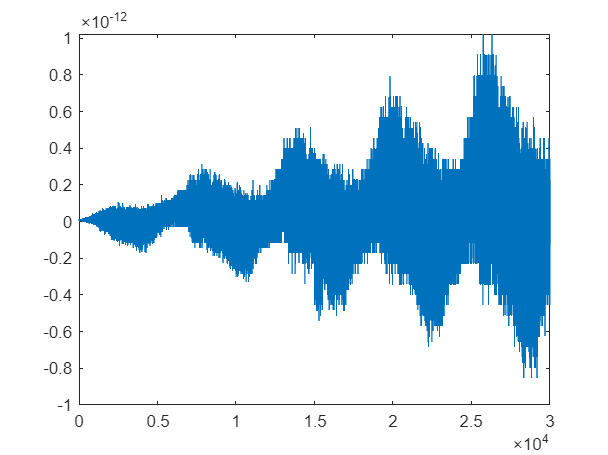

figure; plot(t, yJ3B - y_t)

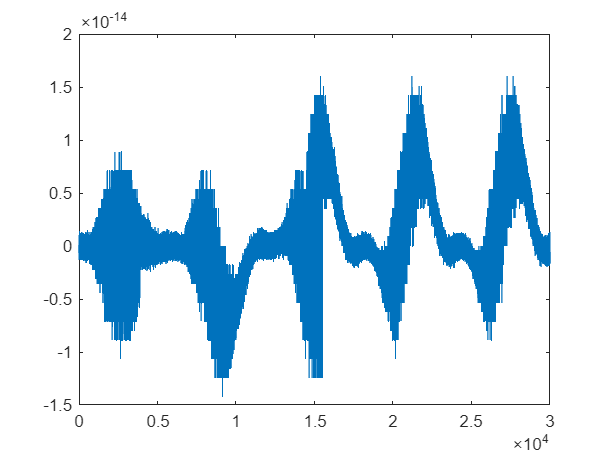

figure; plot(t, zJ3B - z_t)

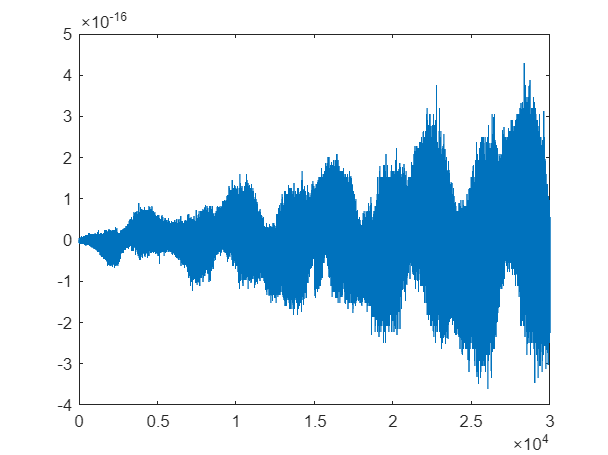




xdotJ3B = (6.*n.*cos((n.*t)./2).*sin((n.*t)./2)).*x0 + cos(n.*t).*dx0 + (4.*cos((n.*t)./2).*sin((n.*t)./2)).*dy0 + (((3.*R.^3.*n.^2.*sin(INC).*cos(omega))./2 - (15.*R.^3.*n.^2.*sin(INC).^3.*cos(omega))./8 - (3.*R.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(omega))./2 - (3.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*sin(omega))./2 + (15.*R.^3.*n.^2.*cos(n.*t).*sin(INC).^3.*cos(omega))./8 - 3.*R.^3.*n.^2.*sin((n.*t)./2).^2.*sin(INC).*cos(omega) + (15.*R.^3.*n.^2.*sin(n.*t).*sin(INC).^3.*sin(omega))./8 + (15.*R.^3.*n.^2.*sin((n.*t)./2).^2.*sin(INC).^3.*cos(omega))./4 - (15.*R.^3.*n.^2.*cos(n.*t).*sin(n.*t).*sin(INC).^3.*sin(omega))./4 - (15.*R.^3.*n.^2.*cos(n.*t).*sin(n.*t).^2.*sin(INC).^3.*cos(omega))./8 + 5.*R.^3.*n.^2.*cos(n.*t).*sin(n.*t).*sin(INC).^3.*sin(omega).^3 + 10.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).^3.*sin(omega).^3 + 30.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).^3.*sin(INC).^3.*sin(omega) - 45.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).^5.*sin(INC).^3.*sin(omega) - (3.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*sin(omega))./2 - 6.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).*sin(omega) - 40.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).^3.*sin(INC).^3.*sin(omega).^3 + 60.*R.^3.*n.^2.*cos((n.*t)./2).*sin((n.*t)./2).^5.*sin(INC).^3.*sin(omega).^3 + (15.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).^3.*sin(omega))./8 - 3.*R.^3.*n.^3.*t.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).*cos(omega) + (15.*R.^3.*n.^3.*t.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).^3.*cos(omega))./4 + (15.*R.^3.*n.^2.*cos(n.*t).*sin(n.*t).^2.*sin(INC).^3.*cos(omega).*sin(omega).^2)./2)./(a.^2.*n)).*J3;
ydotJ3B = (-12.*n.*sin((n.*t)./2).^2).*x0 + (-2.*sin(n.*t)).*dx0 + (1 - 8.*sin((n.*t)./2).^2).*dy0 + ((R.^3.*n.*sin(INC).*sin(omega).*(5.*sin(INC).^2.*sin(omega).^2 - 3))./(2.*a.^2) - (R.^3.*n.*sin(omega + n.*t).*sin(INC).*(5.*sin(omega + n.*t).^2.*sin(INC).^2 - 3))./(2.*a.^2) - (2.*((15.*R.^3.*n.*sin(n.*t).*sin(INC).^3.*cos(omega))./8 - 6.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).*sin(omega) - (15.*R.^3.*n.^2.*t.*sin(INC).^3.*cos(omega))./8 - (5.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*cos(omega))./8 - (15.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3.*sin(omega))./8 + 15.*R.^3.*n.*sin((n.*t)./2).^4.*sin(INC).^3.*sin(omega) - 15.*R.^3.*n.*sin((n.*t)./2).^6.*sin(INC).^3.*sin(omega) - (3.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega))./2 + (3.*R.^3.*n.^2.*t.*sin(INC).*cos(omega))./2 + (5.*R.^3.*n.*sin(n.*t).^2.*sin(INC).^3.*sin(omega).^3)./2 + 10.*R.^3.*n.*sin((n.*t)./2).^2.*sin(INC).^3.*sin(omega).^3 - 20.*R.^3.*n.*sin((n.*t)./2).^4.*sin(INC).^3.*sin(omega).^3 + 20.*R.^3.*n.*sin((n.*t)./2).^6.*sin(INC).^3.*sin(omega).^3 + (15.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).^3.*sin(omega))./8 + (15.*R.^3.*n.^2.*t.*sin((n.*t)./2).^2.*sin(INC).^3.*cos(omega))./4 - (3.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega))./2 + (5.*R.^3.*n.*sin(n.*t).^3.*sin(INC).^3.*cos(omega).*sin(omega).^2)./2 - 3.*R.^3.*n.^2.*t.*sin((n.*t)./2).^2.*sin(INC).*cos(omega)))./a.^2).*J3;
zdotJ3B = (-n.*sin(n.*t)).*z0 + cos(n.*t).*dz0 + (((15.*R.^3.*n.*cos(INC).^3.*sin(n.*t))./4 - (9.*R.^3.*n.*cos(INC).*sin(n.*t))./4 - (5.*R.^3.*n.*cos(2.*omega).*cos(INC).*sin(n.*t))./4 - (5.*R.^3.*n.*sin(2.*omega).*cos(n.*t).*cos(INC))./2 + (5.*R.^3.*n.*sin(2.*omega).*cos(n.*t).^2.*cos(INC))./2 + (5.*R.^3.*n.*cos(2.*omega).*cos(INC).^3.*sin(n.*t))./4 + (5.*R.^3.*n.*sin(2.*omega).*cos(n.*t).*cos(INC).^3)./2 - (5.*R.^3.*n.*sin(2.*omega).*cos(INC).*sin(n.*t).^2)./2 - (5.*R.^3.*n.*sin(2.*omega).*cos(n.*t).^2.*cos(INC).^3)./2 + (5.*R.^3.*n.*sin(2.*omega).*cos(INC).^3.*sin(n.*t).^2)./2 - 5.*R.^3.*n.*cos(2.*omega).*cos(n.*t).*cos(INC).^3.*sin(n.*t) + 5.*R.^3.*n.*cos(2.*omega).*cos(n.*t).*cos(INC).*sin(n.*t))./a.^2).*J3;

x_dot = 3.*n.*sin(2*eta).*x0 ...
    + cos(2*eta).*dx0 ...
    + 2.*sin(2*eta).*dy0 ...
    - (n.*R.^3.*J3)./32/(a^2) .* ( ...    
        15*cos(3*beta9).*sin(INC).^3 ...
        + 15.*cos(2*eta)*cos(3*alpha1).*sin(INC).^3 ...
        + sin(2*eta).*( ...
            35*sin(3*alpha1).*sin(INC).^3 ...
            + 9*sin(alpha1).*(sin(INC) + 5*sin(3*INC)) ...
         ) ...
        + 6*eta.*sin(u).*(sin(INC) + 5*sin(3*INC)) ...
    );
y_dot = -12.*n.*sin(eta).^2.*x0 ...
        - 2.*sin(n.*t).*dx0 ...
        + (1 - 8.*eta.^2).*dy0 ...
        + n*R^3*J3/32/a^2.*( ...
        + 2*sin(2*eta).*( ...    
            + 15*sin(INC).^3*cos(3*alpha1) ...
            + 3*cos(alpha1)*(9*sin(INC) + 5*sin(3*INC)) ...
            - 40*sin(2*eta).^2.*cos(alpha1).^3.*sin(INC).^3 ...
            ) ...
        + 2*cos(2*eta).*sin(INC).*( ...    
            - 35*sin(INC).^2*sin(3*alpha1) ...
            - 12*sin(alpha1)*(2*cos(2*INC) + kappa_i) ...
            - 40*cos(2*eta).^2.*sin(INC).^2.*sin(alpha1).^3 ...
            ) ...
        - 10*sin(3*u).*sin(INC).^3 ...
        ...
        - 60.*sin(u).*sin(4*eta).*sin(2*alpha1).*sin(INC)^3 ...
        ...
        + 60*sin(3*alpha1)*sin(INC)^3 ...
        + 9*sin(alpha1)*(sin(INC) + 5*sin(3*INC)) ...
        ...
        - 12*eta.*cos(u).*(sin(INC) + 5*sin(3*INC)) ...
        );
z_dot = -n.*sin(n.*t).*z0 + cos(n.*t).*dz0 ...
    + (n.*R.^3.*J3)./8/a.^2 .* ( ...
        + sin(2*eta).*cos(INC).*( ...
            -10*sin(INC).^2.*cos(2*alpha1) ...
            + 15*cos(2*INC) ...
            - 3 ...
        ) ...
        - 5*cos(2*eta).*sin(2*alpha1).*( ...
            cos(INC) - cos(3*INC) ...
        ) ...
        + 5*sin(2*u).*( ...
            cos(INC) - cos(3*INC) ...
        ) ...
    );

figure; plot(t, xdotJ3B - x_dot)

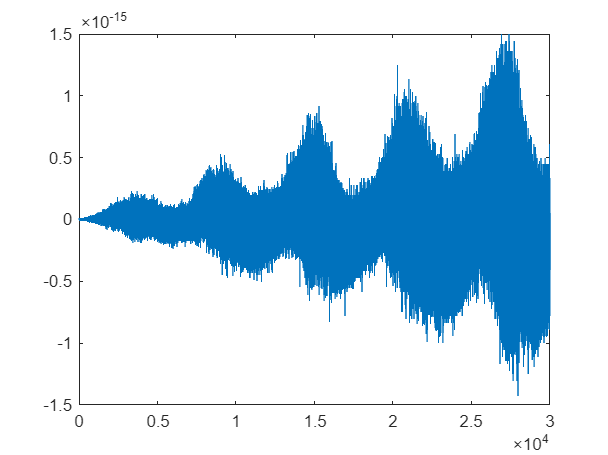

figure; plot(t, ydotJ3B - y_dot)

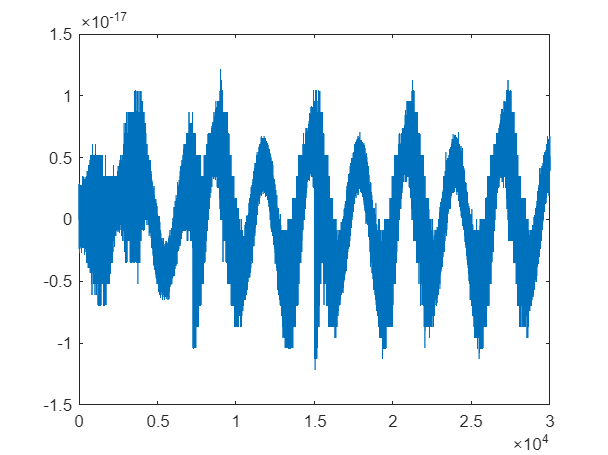

figure; plot(t, zdotJ3B - z_dot)